# Evaluacion parte 2

- para estra trayectoria mapee punto a punto mi silueta con ayuda de el software de geogebre, y luego traslade los puntos obtenidos a este codigo que sigue los mismos principios que en la parte 1, y con un pequeño ajuste en los valores de Velocidad angular (w), velocidad lineal (v), ancho de la muestra (ts), tiempo de simulación (t) y ganacias segun fui haciendo pruebas para coseguir una mejor trayectoria.

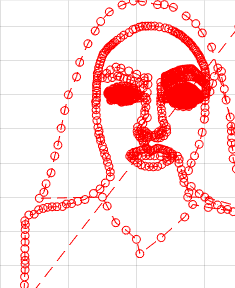

- Tambien hice un molelo diferente para hacer puebas de cual era la mejor trayectoria

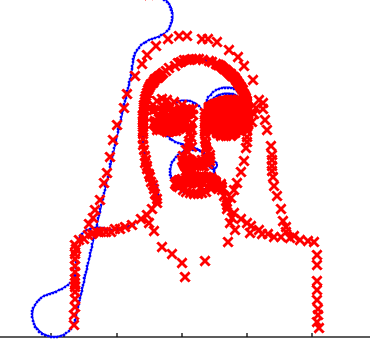

R = 0.2;                        % Wheel radius [m]
L = 0.2;                        % Wheelbase [m]
dd = DifferentialDrive(R,L);

% Sample time and time array
sampleTime = 0.1;               % Sample time [s] (reduced for faster updates)
tVec = 0:sampleTime:250;         % Time array

% Initial conditions
initPose = [1;2;0];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Create lidar sensor
lidar = LidarSensor;
lidar.sensorOffset = [0,0];
lidar.scanAngles = linspace(-pi/2,pi/2,200);
lidar.maxRange = 0.5;

## Path planning and following

Create waypoints

waypoints = [initPose(1:2)'; 
             -5.3110648010426,-6.138300688133;
             -5.2963811806469,-5.8299446598248;
             -5.2890393704491,-5.5803231130991;
             -5.2816975602513,-5.3380433765713;
             -5.2670139398557,-5.1324726910325;
             -5.2670139398557,-4.9636110564828;
             -5.2670139398557,-4.8534839035156;
             -5.2743557500535,-4.7286731301527;
             -5.2743557500535,-4.5084188242183;
             -5.2670139398557,-4.3175317590752;
             -5.2670139398557,-4.126644693932;
             -5.2670139398557,-3.9504412491845;
             -5.2596721296579,-3.8036050452282;
             -5.2743557500535,-3.693477892261;
             -5.1568867868885,-3.5246162577113;
             -5,-3.5;
             -4.8705561891737,-3.3704382435572;
             -4.7384036056131,-3.3337291925681;
             -4.6062510220524,-3.297020141579;
             -4.4740984384918,-3.2823365211834;
             -4.3346040447333,-3.2823365211834;
             -4.1730842203814,-3.2749947109856;
             -4.0556152572164,-3.2015766090074;
             -3.9014372430623,-3.1868929886118;
             -3.7252337983148,-3.1208166968315;
             -3.5123213025782,-3.0694240254468;
             -3.2626997558525,-2.8932205806993;
             -3.0718126907093,-2.7610679971386;
             -2.9137715346754,-2.5847562283363;
             -2.7692063584719,-2.405495409844;
             -2.7692063584719,-2.2609302336405;
             -2.8096846078089,-2.1047998433407;
             -2.8501628571459,-1.9775824882816;
             -2.8848584994347,-1.82723470503;
             -2.936901962868,-1.7404955993079;
             -2.9658149981087,-1.6017130301525;
             -3,-1.5;
             -3.0525541038308,-1.3472783200343;
             -3.0641193179271,-1.2605392143122;
             -3.1103801743122,-1.1564522874457;
             -3.0988149602159,-1.0697131817236;
             -3.1335106025048,-0.9540610407608;
             -3.1624236377455,-0.7574524011241;
             -3.1797714588899,-0.6013220108243;
             -3.185554065938,-0.4394090134764;
             -3.185554065938,-0.2890612302247;
             ];

% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.1;
controller.DesiredLinearVelocity = 0.3;  % Increased speed for faster updates
controller.MaxAngularVelocity = 30;      % Increased max angular velocity

% Vector Field Histogram (VFH) for obstacle avoidance
vfh = controllerVFH;
vfh.DistanceLimits = [0.05 3];
vfh.NumAngularSectors = 36;
vfh.HistogramThresholds = [5 10];
vfh.RobotRadius = L;
vfh.SafetyDistance = L;
vfh.MinTurningRadius = 0.25;

## Simulation loop

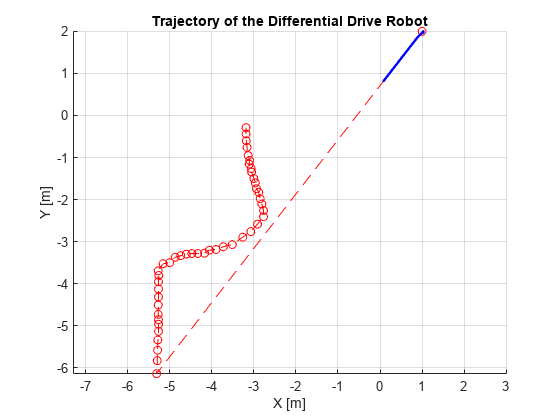

r = rateControl(1/sampleTime);

figure; hold on;
plot(waypoints(:,1), waypoints(:,2), 'ro--'); % Plot waypoints
title('Trajectory of the Differential Drive Robot');
xlabel('X [m]');
ylabel('Y [m]');
grid on;
axis equal;

for idx = 2:numel(tVec)
    % Get the sensor readings
    curPose = pose(:,idx-1);
    ranges = lidar(curPose);
    
    % Run the path following and obstacle avoidance algorithms
    [vRef,wRef,lookAheadPt] = controller(curPose);
    targetDir = atan2(lookAheadPt(2)-curPose(2),lookAheadPt(1)-curPose(1)) - curPose(3);
    steerDir = vfh(ranges, lidar.scanAngles, targetDir);
    if ~isnan(steerDir) && abs(steerDir-targetDir) > 0.1
        wRef = 0.5*steerDir;
    end
    
    % Control the robot
    velB = [vRef;0;wRef];             % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,curPose);  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = curPose + vel*sampleTime;
    
    % Update visualization
    plot(pose(1,idx), pose(2,idx), 'b.');
    drawnow;
    
    waitfor(r);
end


% Plot final trajectory
plot(pose(1,:), pose(2,:), 'b');
legend('Waypoints', 'Trajectory');